# Prac 1

## Q1

(n^2+n)/2

## Q2

There are many ways to look at this data. Consider correlation, and more complex relations.

## Q3

Try 'help load' if you don't know where start

x = load('prac1_q3.dat', 'ASCII');
mean(x)

ans = -2.9842

std(x)

ans = 9.4190

## Q4

Now 'help plot' will be useful

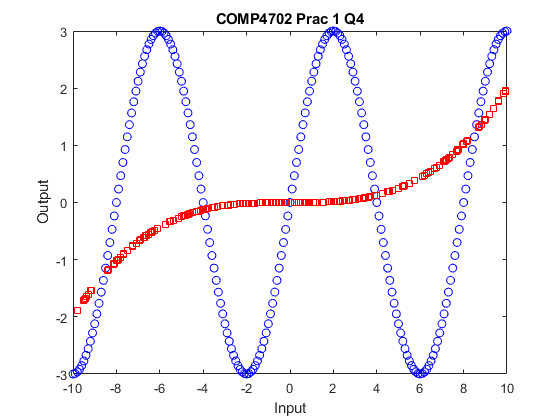

y = load('prac1_q4.dat', 'ASCII');
figure
plot(y(1:end, 1), y(1:end, 2), 'bo', y(1:end, 3), y(1:end, 4), 'rs')
title('COMP4702 Prac 1 Q4')
xlabel('Input')
ylabel('Output')

## Q5

Try 'help randn' if you don't know where to start

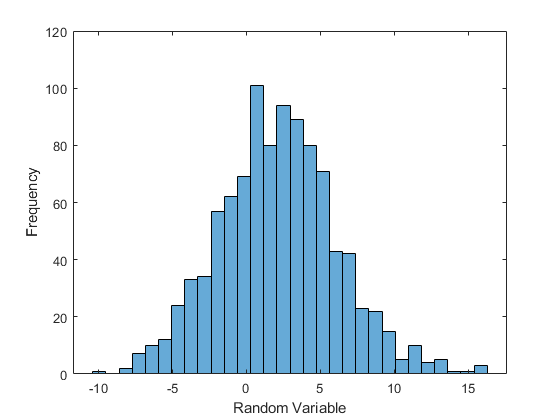

stdDev = 4;
avg = 2;
z = stdDev.*randn([1,1000]) + avg;
figure
histogram(z, 30)
xlabel('Random Variable')
ylabel('Frequency')

## Q6

function out = chunkReversal(in, n)

Calculate quotient and remainder to simplify number of loops and final loop operation.

remainder = rem(length(in), n);
quotient = floor(length(in)/n);

Create space for output vector.

out = zeros(length(in),1);

Loop through whole n-size operations, quotient times (p starts at zero to make indices easier).

for p = 0:(quotient-1)
    

Counts backwards from the end of in, then copies those elements into out, counting forwards through the indices in out.

    out(p*n+1:(p+1)*n) = in(end-n*(p+1)+1:end-n*p);
    

Optional, but useful for debugging. The documentation for the function indictates that we cannot offer an input variable that will toggle this.

    disp(out);
end

Perform the same calculation for the final loop, but using index vector of length remainder.

if remainder ~= 0
    out(end-(remainder-1):end) = in(1:1+(remainder-1));
    disp(out);
end
end